
%r = Eb/N0
r = logspace(0,4,100);
%M = [4, 16, 64, 256, 1024, 4096];
% M = linspace(2,4^6,1000);
% M = round(M/2)*2;
M = 2:2:4096;
L = length(M);

[r, M] = meshgrid(r,M);

legendText = {};
Pb = zeros(size(r));
for k = 1:L
    m = mean(M(k,:));
    Pb(k,:) = getPbQAM(m, r(k,:));
%     semilogy(10*log10(r(k,:)), Pb, 'LineWidth', 2)
%     grid on
%     hold on
%     legendText{k} = strcat(int2str(M(k)), 'QAM');
end

% legend(legendText)
% ylim([1e-14, 1e0])
% ylabel('Bit Error Rate (M-QAM)')
% xlabel('SNR/bit (E_b/N_0) (dB)')

surf(10*log10(r), M, log10(Pb), 'EdgeColor','none', 'FaceColor','interp')
zlabel('log_1_0(Bit Error Rate (M-QAM))')
xlabel('SNR/bit (E_b/N_0) (dB)')
ylabel('Number of Constellation Points')
grid on
yticks([4, 16, 64, 256, 1024, 4096])
ylim([4, 4096])
title('QAM Bit Error Rate')
colormap("jet")
c = colorbar();
set(gca, 'yscale', 'log')
zlim([-14, 0])
% set(gca, 'ColorScale', 'log')
caxis([-14 0])
view(2)
ylabel(c, 'log_1_0(BER)')


BER_thres = 1e-3*ones(size(Pb));


zdiff = Pb - BER_thres;
C = contours(10*log10(r), M, zdiff, [0 0]);
% Extract the x- and y-locations from the contour matrix C.
xL = C(1, 2:end);
yL = C(2, 2:end);
% Interpolate on the first surface to find z-locations for the intersection
% line.
zL = interp2(10*log10(r), M, Pb, xL, yL);
% Visualize the line.
line(xL, yL, zL, 'Color', 'k', 'LineWidth', 3);



% Find M, SNR when Pb = 10^-3
% idx = find(Pb < 1e-3);


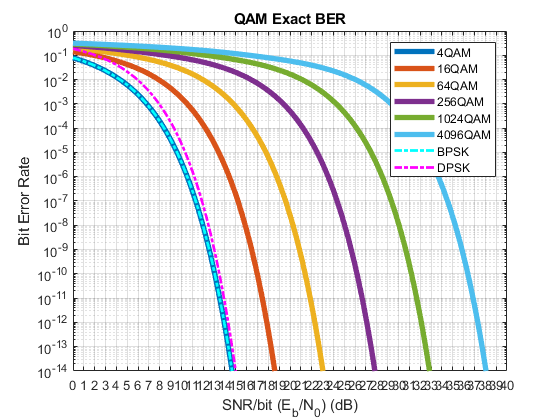


r = logspace(0,6,1000);
legendText = {};
% Pb2 = zeros(size(r));
m = [1, 2, 3, 4, 5, 6];
m = 4.^m;
hold off
for k = 1:length(m)
    Pb2 = getPbQAM(m(k), r); 
    semilogy(10*log10(r), Pb2, 'LineWidth', 4)
    grid on
    hold on
    legendText{k} = strcat(int2str(m(k)), 'QAM');
end

y = 0.5*erfc(sqrt(2*r)/sqrt(2));
% Pb2 = getPbQAM(4, r);
semilogy(10*log10(r), y, 'LineWidth', 2, 'LineStyle', "-.", 'Color', 'c')
legendText{end + 1} = 'BPSK';

y = 0.5*exp(-r);
semilogy(10*log10(r), y, 'LineWidth', 2, 'LineStyle',"-.", 'Color', 'm')
legendText{end + 1} = 'DPSK';

legend(legendText)
ylim([1e-14, 1e0])
ylabel('Bit Error Rate')
xlabel('SNR/bit (E_b/N_0) (dB)')
yticks(10.^(-14:0))
xticks(0:40)
title('QAM Exact BER')

% Adaptive Modulation Gen
% BER_max = 1e-3;
% SNR = linspace(0, 20, 10000);
% SNR = 10.^(SNR/10);

% For M-QAM, find SNR_thres(M)
% Then SNR = SNR_thres(M) + margin
% Want max data rate

% QAM Data Rate

% SNR_thres = (2.^eta - 1)./eta;
% SNR_thres = 10*log10(SNR_thres);


SNR = linspace(0, 20, 1000);
Margin = 0;
SNR_InputThres = SNR - Margin;
SNR_InputThres = 10.^(SNR_InputThres/10);

% M_Possible = [4, 16, 64, 256, 1024, 4096];
% M_Possible = flip(M_Possible);
% BER_Thres = 1e-3;
% M = zeros(size(SNR));
% for k = 1:length(SNR_InputThres)
%     for v = 1:length(M_Possible)
%         BER = getPbQAM(M_Possible(v), SNR_InputThres(k));
%         if BER <= BER_Thres
%             break
%         end
%     end
%     
%     M(k) = M_Possible(v);
% end





M = zeros(size(SNR));
for k = 1:length(SNR)
    if SNR(k) >= 7 && SNR(k) < 9
        M(k) = 4;
    elseif SNR(k) >= 9 && SNR(k) < 13
        M(k) = 16;
    elseif SNR(k) >= 13 && SNR(k) < 18
        M(k) = 64;
    elseif SNR(k) >= 18 
        M(k) = 256;
    end
end

BW = 20e6;
eta = log2(M);
Rb = eta*BW;
channelCapacity = BW*log2(1 + 10.^(SNR/10));


RbLim = min(Rb, channelCapacity);
etaLim = RbLim/BW;
MLim = 2.^etaLim;
% MLim = round(MLim/4)*4;
MLim= 4.^(floor(log(MLim)/log(4)));
etaLim = log2(MLim);
RbLim = etaLim*BW;

subplot(2,1,1)
% plot(SNR, Rb/1e6)
hold on

plot(SNR, RbLim/1e6, 'LineWidth', 2)
plot(SNR, channelCapacity/1e6, 'LineWidth', 2)
grid on
xlabel('SNR/bit (E_b/N_0) (dB)')
ylabel('Data Rate (Mbps)')
legend('Adaptive Modulation Scheme', 'Max Channel Capacity')

subplot(2,1,2)
plot(SNR, M, 'LineWidth', 2)
hold on
plot(SNR, MLim, 'LineWidth', 2)
grid on
xlabel('SNR/bit (E_b/N_0) (dB)')
ylabel('Number of Constellation Points')
legend('Adaptive Modulation Scheme', 'Adaptive Modulation Scheme with Capacity Limits')


% End goal: plot data rate vs SNR + block diagram
% delaySpread0 = 0;
delaySpread1 = 10e-9;
maxBw = 1/(5*delaySpread1)




getPbQAM(16, r)

ans =     41.8928e-003


function Pb = getPbQAM(M, r)
    sum = zeros(size(r));
    for k = 1:log2(sqrt(M))
        sum = sum + getQAMPbk(k, M, r);
    end
    Pb = sum/log2(sqrt(M));
end




function Pbk = getQAMPbk(k, M, r)
    topBound = (1 - 2^(-k))*sqrt(M) - 1;
    sum = zeros(size(r));
    for n = 0:topBound
        temp = n*2^(k-1);
        temp = temp/sqrt(M);
        temp = floor(temp);
        temp = (-1)^temp;
        
        temp2 = n*2^(k-1);
        temp2 = temp2/sqrt(M);
        temp2 = temp2 + 0.5;
        temp2 = floor(temp2);
        temp2 = 2^(k-1) - temp2;
        
        temp3 = 3*log2(M)/(2*(M-1));
        temp3 = temp3*r;
        temp3 = sqrt(temp3);
        temp3 = (2*n + 1)*temp3;
        temp3 = erfc(temp3);
        
        sum = sum + temp*temp2*temp3;
    end
    Pbk = sum/sqrt(M);
end



